**Read all instructions carefully!**

**Instructions on what to turn in: **

Download the folder lab4files to your machine. Inside you will find the following files: 

- lab4_lastname.mlx (rename this file to include your last name)

What you will need to turn in on Canvas. Upload the following 2 files:

- lab4_lastname.pdf  (instructions on how to generate this below)

- lab4_lastname.mlx

How to generate lab4_lastname.pdf. 

Once you have completed all the parts of the assignment and are satisfied with your work, go View in the top bar and click Output Inline - this makes it so that the grader can easily follow your work. Run lab4_lastname.mlx one more time then go to Live Editor and click Export then choose PDF. A pdf file with the same name as the Live script will be generated with answers to all the parts. 

**Specific instructions for the assignment:**

- In Problem 2 you will create a Matlab function within a script. Any Matlab functions defined within a script (Live or otherwise) should appear at the very end of the script. Any calls to that functions will be above the function. 

- To make your work easy to grade, please suppress all outputs except for the parts that explictly say not to suppress output. This is most important for any Matlab functions you develop! Please make sure everything runs.  

**Problem 1**

format long % shows output with more digits

**a)** Plot the function $f(x) = \frac{1}{1+12x^2}$ on $[-1,1]$ using 100 evenly spaced points. 

f = @(x) 1 ./ (1 + 12*x.^2);
x = linspace(-1,1,100);
plot(x,f(x));

**b)** Use Lagrange Interpolation to approximate the function $f(x) = \frac{1}{1+12x^2}$ using the nodes $x_0 = -1, x_1 = 0, x_2 = 1$. Define$L_0(x), \quad  L_1(x) , \quad  L_2(x)$ then compute $P_2(x) = \sum_{k=0}^2 f(x_k)L_k(x)$. Use anonymous functions.

x0 = -1;
x1 = 0;
x2 = 1;
L0 = @(x) ((x - x1) .* (x - x2)) / ((x0 - x1) * (x0 - x2));
L1 = @(x) ((x - x0) .* (x - x2)) / ((x1 - x0) * (x1 - x2));
L2 = @(x) ((x - x0) .* (x - x1)) / ((x2 - x0) * (x2 - x1));
P2 = @(x) f(x0) * L0(x) + f(x1) * L1(x) + f(x2) * L2(x);

**c)** Plot $P_2(x)$ on the same figure with $f(x)$ using 100 evenly spaced points. Use different colors for the plots.

hold on
plot(x,P2(x));
hold off

**d)** Use Lagrange interpolation to approximate the same function using the nodes $\{-1,-0.5,0,0.5,1\}$. Define the required basis functions $L_k(x)$ then compute $P_4(x)$. Use anonymous functions. 

x0 = -1;
x1 = -0.5;
x2 = 0;
x3 = 0.5;
x4 = 1;
L0 = @(x) ((x - x1) .* (x - x2) .* (x - x3) .* (x - x4)) / ((x0 - x1) * (x0 - x2) * (x0 - x3) * (x0 - x4));
L1 = @(x) ((x - x0) .* (x - x2) .* (x - x3) .* (x - x4)) / ((x1 - x0) * (x1 - x2) * (x1 - x3) * (x1 - x4));
L2 = @(x) ((x - x0) .* (x - x1) .* (x - x3) .* (x - x4)) / ((x2 - x0) * (x2 - x1) * (x2 - x3) * (x2 - x4));
L3 = @(x) ((x - x0) .* (x - x1) .* (x - x2) .* (x - x4)) / ((x3 - x0) * (x3 - x1) * (x3 - x2) * (x3 - x4));
L4 = @(x) ((x - x0) .* (x - x1) .* (x - x2) .* (x - x3)) / ((x4 - x0) * (x4 - x1) * (x4 - x2) * (x4 - x3));
P4 = @(x) f(x0) * L0(x) + f(x1) * L1(x) + f(x2) * L2(x) + f(x3) * L3(x) + f(x4) * L4(x);

**e) **Plot $P_4(x)$ on the same figure with $f(x)$ and $P_2(x)$ using 100 evenly spaced points. Use different colors for the plots. Add a legend. 

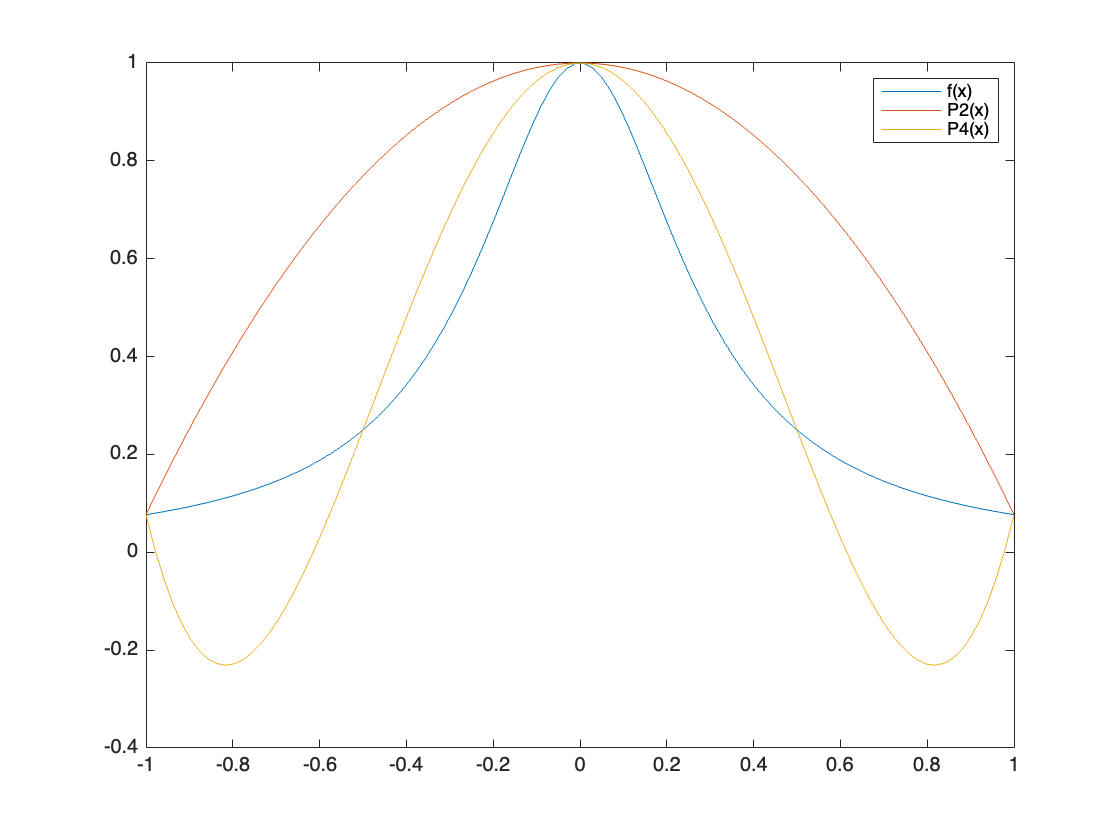

hold on
plot(x,P4(x));
legend('f(x)','P2(x)','P4(x)');
hold off

**f)**  Compute the absolute errors when $P_2$ and $P_4$ are used to approximate $f(0.45)$. *(Do not suppress output)*

P2_err = abs(f(0.45) - P2(0.45))

P2_err =    0.521531733572550


P4_err = abs(f(0.45) - P4(0.45))

P4_err =    0.074318272034088


**Problem 2: **

***Work on part b) before part a)!***

**a)** Test your function $\texttt{newttd}$ developed below using data from Table 3.10 in Burden, Faires, and Burden. i.e. create two vectors : one containing the values of $x$ and another containing the values of $f(x)$. Then use these vectors as inputs to $\texttt{newtdd}$. *(Do not suppress output from your function call).*

*The values in your output matrix should match the values in the Table 3.11 - from column 3 onwards.*

x = [1.0,1.3,1.6,1.9,2.2];
y = [0.7651977,0.6200860,0.4554022,0.2818186,0.1103623];
newtdd(x,y)

ans =    0.765197700000000                   0                   0                   0                   0
   0.620086000000000  -0.483705666666666                   0                   0                   0
   0.455402200000000  -0.548946000000000  -0.108733888888889                   0                   0
   0.281818600000000  -0.578612000000000  -0.049443333333334   0.065878395061728                   0
   0.110362300000000  -0.571520999999999   0.011818333333335   0.068068518518521   0.001825102880660


**b)** Create a Matlab function that implements Algorithm 3.2 from Burden,Faires, Burden below. Adjust the indexing from the pseudocode to match Matlab indexing. 

Copy and paste the following starter code into the grey box below and complete your function : 

function F = newtdd(x,f)
% Implements Newton's Divided Differences formula for interpolation
% Inputs: x - vector of interpolation nodes 
%         f - vector of function values at the nodes 

n = length(x);
F = zeros(n,n);
F(:,1) = f;

% STEP 1
for i = 2:n
    for j = 2:i
       F(i,j) = (F(i,j-1) - F(i-1,j-1)) / (x(i) - x(i-j+1));
    end
end

end